# Disease/Virus/Infection Simulator for the World Health Organisation

#### Group 14 Original Creation Livescript

By: Caleb Crook, Ash Phillips, Jud Moy and Damini Raniga

## Aim:

#### The Problem:

Large scale disease, viruse and infection outbreaks are a threat that continues to exist for humanity even in this technologically advance world. Outbreaks like these have the power to  cause mass deaths, disable people for life and significantly reduce the living standards for people in affected areas. But no ones knows the extent of the effects until they happen in real life and cause great destruction.

Our group wanted to create a simulation program that can simulate the effects of potential disease, virus and infection outbreaks and analyse the results of an outbreak. This simulation was created for the World Health Organisation (WHO) so that they could potentially see the effects of an outbreak and implements actions to reduce risks of a outbreak occuring and saving countless lives. 

#### The Goal:

Yes we could of created a simulation for the WHO that could model some diseases in some countries; but we wanted to go beyond that by creating a flexible enough program that could model any disease in any part of the globe. 

To achieve this goal we combined our knowledge of Cellular Automata and Image Processing  and created a game of life simulation that was based on a population desity heat map of a particular country. In order for this single software to be used for every country or city we created the code to work with any screen-shot of the population density heat map from this particular website [http://luminocity3d.org/WorldPopDen/#3/12.00/10.00](http://luminocity3d.org/WorldPopDen/#3/12.00/10.00)

**Note that the image from the website have to be edited slightly to work well with the simulation. Smaller imager were required for the simulation to run in this livescript rather than a normal script. In the folder there is a series of images for you try, please select one and follow through with the report**

This allowed us to run our simluation and measure the spread of disease in any country we wanted, as every country in this map hold the same legend and population density levels. Including this feature was essential as it allowed us to create a simulation that can compare the spread of disease in different countries, geographical locations, cities, and any different point on the world map desired; hence making our simulation more applicable to the real world and more appealing to the WHO. 

We will now step through the proces we have taken to create this simulation with a particular image example.

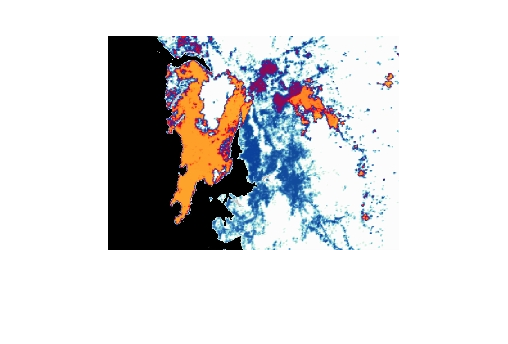

% We have chosen this image to fill out our report, but please
% feel free to choose any image in the folder that you would like.
% PLEASE NOTE: The simulation works when the all sections of this mlx file
% are running together. (Run all button)
imagepic = ('Bombay.jpg');
imshow(imagepic)

In order for our simulation to work properly we needed to ensure that the simulation will mask and run with any size image. Therefore, we created variables for the length, width, and dimension of a image.

image = imread(imagepic);
[Rows,Columns,dim] = size(image);

## Auto-Masking an Image: Part 1 - The Legend

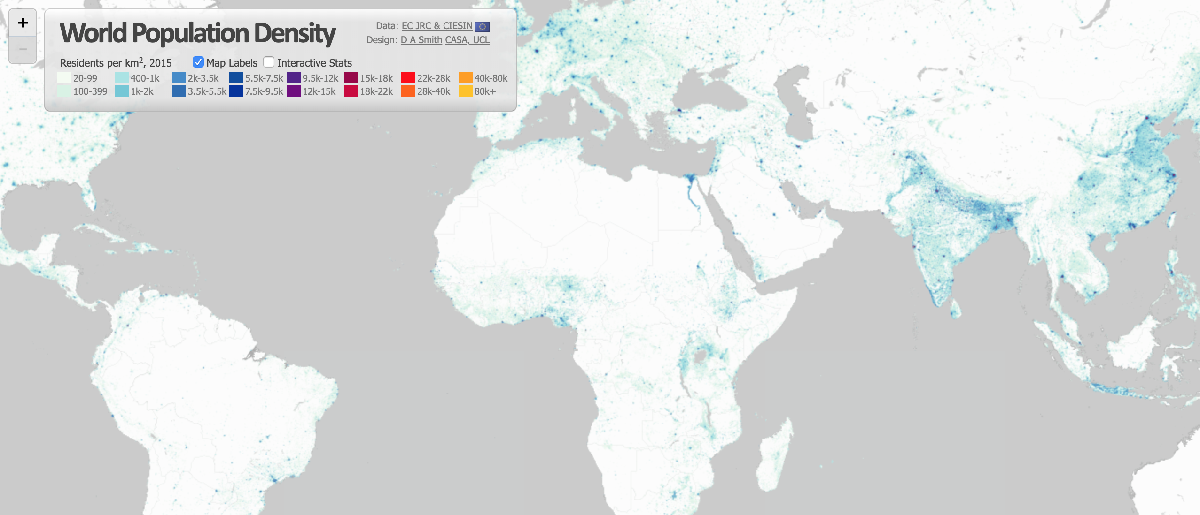

As seen in the image above, the map contains a legend in the top left corner of the webpage. This legend shows 16 levels of population density and the associated colours with each different level. We masked the image accordingly into their respective levels so we could distinguish between ocean and land. By doing this, we now harness the ability to change the way that the virus spreads through the population as it enters the different areas of a country that have differing population densities.

This was essential to achieving our goal in creating a simulation that can model any disease in the real world as, let's face it, most of the good hospitals, doctors, and medical supplies are located in the big cities where there is very high population density. Thus, people in rural or developing areas do not have the same access to the medical supplies needed; also, their standards of living may be lower, allowing disease and infection to most likely spread faster.

We created a mask that allowed us to change the probabilies of a cell becoming infected, being cured, dying, becoming repopulated (alive), or unoccupied, based on the population density level the cell is in. This also allowed our similuation to be more applicable to real diseases.

In order to create our mask we first took the RGB values of the 16 levels of population density from the legend on the map

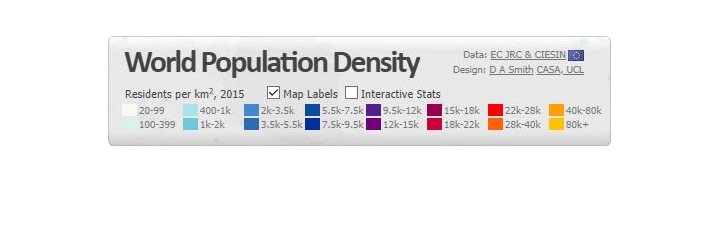

imshow('legend.jpg')

We did this by selecting the points in the coloured boxes on the legend and associated that point with a specific level. 

Level 1 is 20 - 99 people per km squared

Level 2 is 100 - 399 people per km squared

Level 3 is 400 - 1K people per km squared

.....

Level 16 is 80K+ people per km squared

*For code purposes we shortened Level to l; eg, Level 1 = l1, Level 2 = l2,...*

legend_1 = imread('legend.jpg');
l1 = legend_1(74,24,:);
l2 = legend_1(88,24,:);
l3 = legend_1(74,84,:);
l4 = legend_1(88,84,:);
l5 = legend_1(74,144,:);
l6 = legend_1(88,144,:);
l7 = legend_1(74,204,:);
l8 = legend_1(88,204,:);
l9 = legend_1(74,264,:);
l10 = legend_1(88,264,:);
l11 = legend_1(74,324,:);
l12 = legend_1(88,324,:);
l13 = legend_1(74,384,:);
l14 = legend_1(88,384,:);
l15 = legend_1(74,448,:);
l16 = legend_1(88,448,:);

Now, we found the R, G, B values at each level and assigned them a variable name

Level 1 R = l1r

Level 1 G = l1g

Level 1 B = l1b

etc.

l1r = l1(1,1,1);
l1g = l1(1,1,2);
l1b = l1(1,1,3);

l2r = l2(1,1,1);
l2g = l2(1,1,2);
l2b = l2(1,1,3);

l3r = l3(1,1,1);
l3g = l3(1,1,2);
l3b = l3(1,1,3);

l4r = l4(1,1,1);
l4g = l4(1,1,2);
l4b = l4(1,1,3);

l5r = l5(1,1,1);
l5g = l5(1,1,2);
l5b = l5(1,1,3);

l6r = l6(1,1,1);
l6g = l6(1,1,2);
l6b = l6(1,1,3);

l7r = l7(1,1,1);
l7g = l7(1,1,2);
l7b = l7(1,1,3);

l8r = l8(1,1,1);
l8g = l8(1,1,2);
l8b = l8(1,1,3);

l9r = l9(1,1,1);
l9g = l9(1,1,2);
l9b = l9(1,1,3);

l10r = l10(1,1,1);
l10g = l10(1,1,2);
l10b = l10(1,1,3);

l11r = l11(1,1,1);
l11g = l11(1,1,2);
l11b = l11(1,1,3);

l12r = l12(1,1,1);
l12g = l12(1,1,2);
l12b = l12(1,1,3);

l13r = l13(1,1,1);
l13g = l13(1,1,2);
l13b = l13(1,1,3);

l14r = l14(1,1,1);
l14g = l14(1,1,2);
l14b = l14(1,1,3);

l15r = l15(1,1,1);
l15g = l15(1,1,2);
l15b = l15(1,1,3);

l16r = l16(1,1,1);
l16g = l16(1,1,2);
l16b = l16(1,1,3);

We first believed that we could construct our mask using only these values; however, after some tests we saw that not every point on the map have the same specific RGB value as their associated level colour. There is a slight variance in colours across the map that are not visible to the eye, yet they still resemble the colours in the legend. However, as they are not that exact colour, when we attempted to complete the masking we found there to high levels of 'noise'. This noise would disrupt the accuracy of our simluation, and thus it needed to be removed.

## Auto-Masking an Image: Part 2 - The Image

We attempted to reduce the 'noise' and create a cleaner, more defined masked image by setting a tolerance. This tolerance could be any number, but it basically acts as a range. Any RGB values in a particular level that are slightly off can be corrected if they are within the range of the specific value + or - the tolerance. Anything outside of this range will be set to 0. While we will never be able to auto-mask an image perfectly, if we can make it as clean as possible the results of our simulation will prove to be more accurate, and hence of more use to the WHO.

So, first we set the tolerance.

%Tolerance = t
t = 17; 
% The number 17 was chosen after many tests as it proved 
% to be the number that was the most effective in removing
% noise and did not effect other sections of the image,
% such as the land.
bt = 12; % This is the tolerance for only the blue components.
% This needs to be smaller due to the lower "spread" of blue.
% A higher blue tolerance would have affected the other sections
% of the image more due to that lower spread.

We then split the image we are simulating into it 3 RGB values.

imageR = image(:,:,1);
imageG = image(:,:,2);
imageB = image(:,:,3);

We then applied that tolerance to every level's RGB components, and created a new matrix.

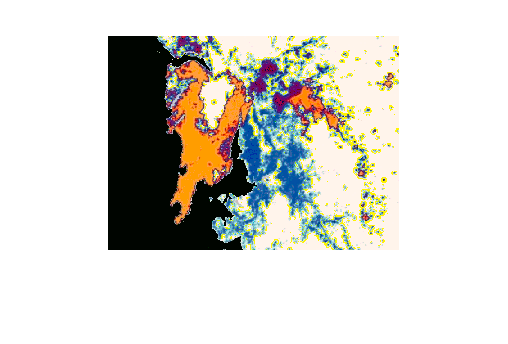

empty_rgb_matrix = zeros(Rows,Columns,dim); % Creating a matrix the same size as the image.
image_rgbtolerated = uint8(empty_rgb_matrix); % Making this matrix into a uint8 matrix, which is what all RGB images are.

imagergbtoleratedR = image_rgbtolerated(:,:,1);
imagergbtoleratedG = image_rgbtolerated(:,:,2);
imagergbtoleratedB = image_rgbtolerated(:,:,3);

% Tolerating Red Component
imagergbtoleratedR(imageR >= l1r-t & imageR <= l1r+t) = l1r;
imagergbtoleratedR(imageR >= l2r-t & imageR <= l2r+t) = l2r;
imagergbtoleratedR(imageR >= l3r-t & imageR <= l3r+t) = l3r;
imagergbtoleratedR(imageR >= l4r-t & imageR <= l4r+t) = l4r;
imagergbtoleratedR(imageR >= l5r-t & imageR <= l5r+t) = l5r;
imagergbtoleratedR(imageR >= l6r-t & imageR <= l6r+t) = l6r;
imagergbtoleratedR(imageR >= l7r-t & imageR <= l7r+t) = l7r;
imagergbtoleratedR(imageR >= l8r-t & imageR <= l8r+t) = l8r;
imagergbtoleratedR(imageR >= l9r-t & imageR <= l9r+t) = l9r;
imagergbtoleratedR(imageR >= l10r-t & imageR <= l10r+t) = l10r;
imagergbtoleratedR(imageR >= l11r-t & imageR <= l11r+t) = l11r;
imagergbtoleratedR(imageR >= l12r-t & imageR <= l12r+t) = l12r;
imagergbtoleratedR(imageR >= l13r-t & imageR <= l13r+t) = l13r;
imagergbtoleratedR(imageR >= l14r-t & imageR <= l14r+t) = l14r;
imagergbtoleratedR(imageR >= l15r-t & imageR <= l15r+t) = l15r;
imagergbtoleratedR(imageR >= l16r-t & imageR <= l16r+t) = l16r;

% Tolerating Green Component
imagergbtoleratedG(imageG >= l1g-t & imageG <= l1g+t) = l1g;
imagergbtoleratedG(imageG >= l2g-t & imageG <= l2g+t) = l2g;
imagergbtoleratedG(imageG >= l3g-t & imageG <= l3g+t) = l3g;
imagergbtoleratedG(imageG >= l4g-t & imageG <= l4g+t) = l4g;
imagergbtoleratedG(imageG >= l5g-t & imageG <= l5g+t) = l5g;
imagergbtoleratedG(imageG >= l6g-t & imageG <= l6g+t) = l6g;
imagergbtoleratedG(imageG >= l7g-t & imageG <= l7g+t) = l7g;
imagergbtoleratedG(imageG >= l8g-t & imageG <= l8g+t) = l8g;
imagergbtoleratedG(imageG >= l9g-t & imageG <= l9g+t) = l9g;
imagergbtoleratedG(imageG >= l10g-t & imageG <= l10g+t) = l10g;
imagergbtoleratedG(imageG >= l11g-t & imageG <= l11g+t) = l11g;
imagergbtoleratedG(imageG >= l12g-t & imageG <= l12g+t) = l12g;
imagergbtoleratedG(imageG >= l13g-t & imageG <= l13g+t) = l13g;
imagergbtoleratedG(imageG >= l14g-t & imageG <= l14g+t) = l14g;
imagergbtoleratedG(imageG >= l15g-t & imageG <= l15g+t) = l15g;
imagergbtoleratedG(imageG >= l16g-t & imageG <= l16g+t) = l16g;

% Tolerating Blue Component
imagergbtoleratedB(imageB >= l1b-t & imageB <= l1b+t) = l1b;
imagergbtoleratedB(imageB >= l2b-t & imageB <= l2b+t) = l2b;
imagergbtoleratedB(imageB >= l3b-t & imageB <= l3b+t) = l3b;
imagergbtoleratedB(imageB >= l4b-t & imageB <= l4b+t) = l4b;
imagergbtoleratedB(imageB >= l5b-t & imageB <= l5b+t) = l5b;
imagergbtoleratedB(imageB >= l6b-t & imageB <= l6b+t) = l6b;
imagergbtoleratedB(imageB >= l7b-t & imageB <= l7b+t) = l7b;
imagergbtoleratedB(imageB >= l8b-t & imageB <= l8b+t) = l8b;
imagergbtoleratedB(imageB >= l9b-t & imageB <= l9b+t) = l9b;
imagergbtoleratedB(imageB >= l10b-t & imageB <= l10b+t) = l10b;
imagergbtoleratedB(imageB >= l11b-t & imageB <= l11b+t) = l11b;
imagergbtoleratedB(imageB >= l12b-t & imageB <= l12b+t) = l12b;
imagergbtoleratedB(imageB >= l13b-t & imageB <= l13b+t) = l13b;
imagergbtoleratedB(imageB >= l14b-t & imageB <= l14b+t) = l14b;
imagergbtoleratedB(imageB >= l15b-t & imageB <= l15b+t) = l15b;
imagergbtoleratedB(imageB >= l16b-t & imageB <= l16b+t) = l16b;

image_rgbtolerated(:,:,1) = imagergbtoleratedR;
image_rgbtolerated(:,:,2) = imagergbtoleratedG;
image_rgbtolerated(:,:,3) = imagergbtoleratedB;


imshow(image_rgbtolerated)

As we are working with a coloured image, each point has 3 values; R (red), G (green), and B (blue). However, in order for us to be able to run celluar automata we need a singular value to represent a specfic colour, and thus a specific level. Therefore, having a greyscaled image is more favourable, as every shade of grey is represented by a single number between 0 and 255. To do this, we needed use the command 'rgb2gray' to change this colour image into a greyscale image. 

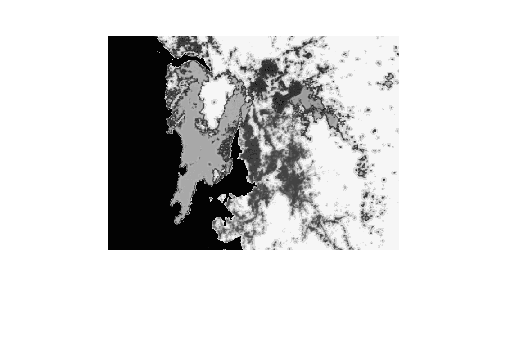

grey = rgb2gray(image_rgbtolerated); %Turning image_rgbtolerated into a greyscale image.
imshow(grey)

As you can see from the image above, the greyscale image still contains some noise as there are still varying values of grey that were not accounted for. So, we ran this image again through a tolerance. However, not with a single value tolerance. In order to get the cleanest image possible we manually tested several values that could be contained in the image by comparing a greyscale image of the original legend.

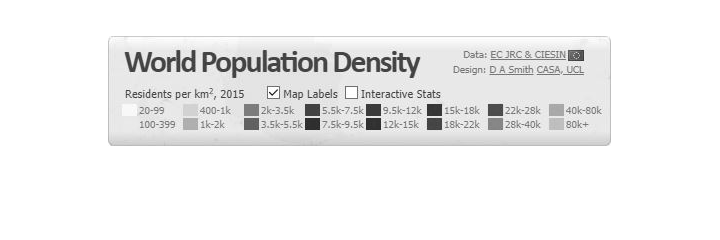

greylegend = rgb2gray(legend_1);
imshow(greylegend)

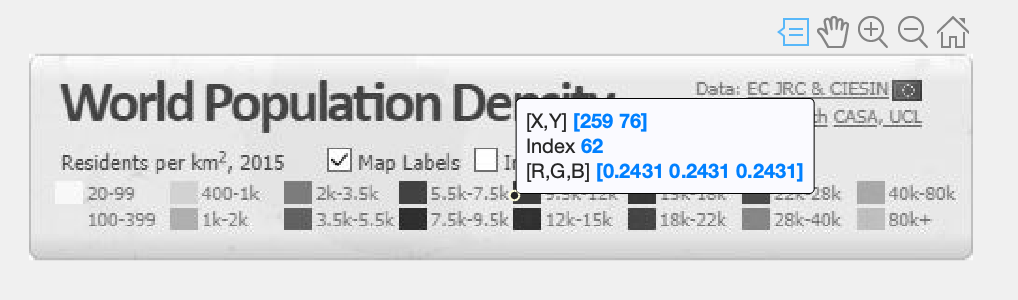

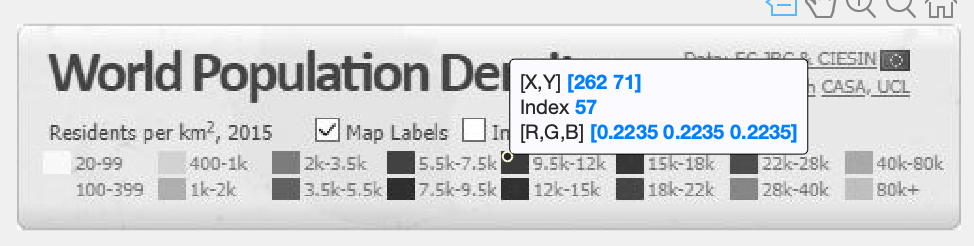

Inserted above you can see that we used the data cursor tool on different pixels in a single square of colour. The results indicate that the colour for that population density level held varying grey scale indexes for the different pixels in that same square (62 and 57).

To account for this we ran the data cursor tool over each square and found a range of values corresponding to a single level.

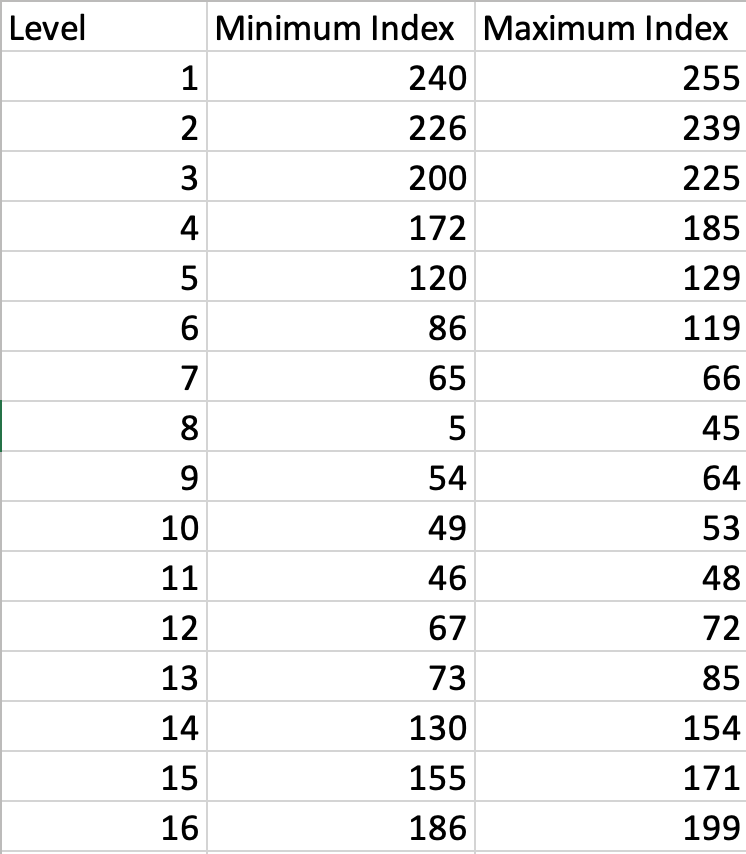 

Above is a table showing the range of values found. Clearly, these ranges are not a very consitent size per level. We ran into a problem when trying to find a specific range of values that correspond to a specific level. Referring back to the image of the legend, we can see that as the level increases the colour becomes darker to a point (level 8) and then the colour becomes lighter again as the level increases. This means that some pixels cannot be distinguished between two different levels. 

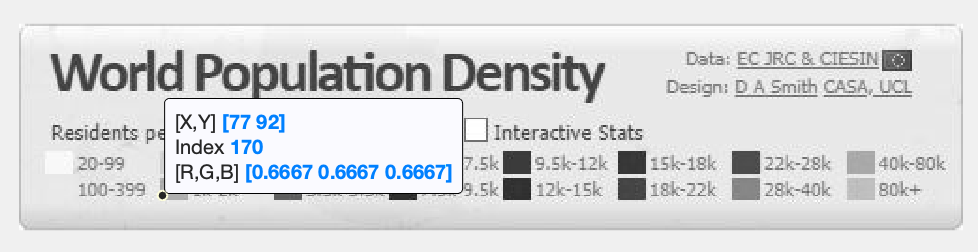

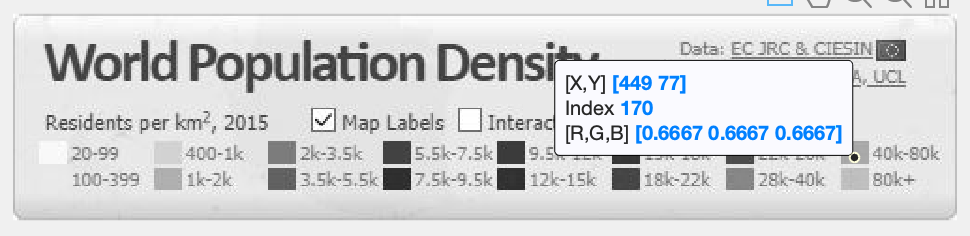

For example, you can see in the two images above that two pixels were selected from level 4 and level 15, but they both had the same greyscale index. Not having a distinct colour difference between two levels does not bode well for our simulation as if we had decided to create a simulation with this image, the simulation may mistake a pixel to be in the wrong level and hence perform an action that was not meant to be executed on that cell. This would therefore distort the results we would recieve and not provide accurate information to the WHO. This is why the greyscale index ranges for each level are not consistent sizes, as we manually had to account for this and changed the range values for each level to be different from every other level, but still account for all 255 index values (0 - 4 is for the ocean).

Even with these unique ranges, its not logical for a higher population density level to have a very similar shade to a lower level. This was fine when the image was in RGB because you could distinguish between the colours. However, now, you can barely see a difference between two very different levels. It is more logical for the darker shades to represent higher population density levels, whereas lighter shades should be used to represent the lower levels. 

To fix this problem, we used the unique ranges of each level and made every cell that was within a particular range a different shade of grey. Level 1 is set to have a grey scale index of 240, Level 2 has an index value of 225, Level 3's index is 210; therefore, as the level increases the index will decrease in increments of 15. This creates a smooth gradient of greys from the level 1 to level 16 which makes the image more logical but also makes it easier for the cellular automata to occur as two totally different levels will not have similar grey indexes.

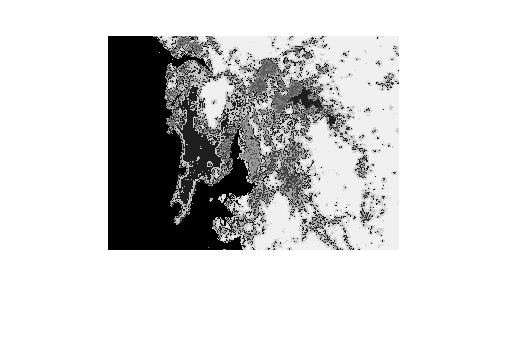

empty_greyscale_matrix = zeros(Rows,Columns); % Creating a matrix the same size as the image.
greytolerated = uint8(empty_greyscale_matrix); % Converting this matrix into a uin8 matrix.
% This new matrix was created so the risk of remasking and changing cells that were already changed was
% minimised.

% Level 1
greytolerated(grey >= 240) = 240;
% Level 2
greytolerated(grey >= 226 & grey <= 239) = 225;
% Level 3
greytolerated(grey >= 200 & grey <= 225) = 210;
% Level 4
greytolerated(grey >= 172 & grey <= 185) = 195;
% Level 5
greytolerated(grey >= 120 & grey <= 129) = 180;
% Level 6
greytolerated(grey >= 86 & grey <= 119) = 165;
% Level 7
greytolerated(grey >= 65 & grey <= 66) = 150;
% Level 8
greytolerated(grey >= 5 & grey <= 45) = 135;
% Level 9
greytolerated(grey >= 54 & grey <= 64) = 120;
% Level 10
greytolerated(grey >= 49 & grey <= 53) = 105;
% Level 11
greytolerated(grey >= 46 & grey <= 48) = 90;
% Level 12
greytolerated(grey >= 67 & grey <= 72) = 75;
% Level 13
greytolerated(grey >= 73 & grey <= 85) = 60;
% Level 14
greytolerated(grey >= 130 & grey <= 154) = 45;
% Level 15
greytolerated(grey >= 155 & grey <= 171) = 30;
% Level 16
greytolerated(grey >= 186 & grey <= 199) = 15;
% Ocean
greytolerated(grey <= 4) = 0;

imshow(greytolerated)

There you have it! A masking generator that will produce a clean masked image of what ever country, or city, you feed it (given that it is from the specific website provided, and is edited slightly).

This image is now perfect to create the second part of the code; the actual simulation.

## Making the Simulation: Part 1 - Setting Initial Population Densities

Once our image was suitably masked, we could start creating the simulation that will occur over it.

To synthesise the cellular automata simulation and the masked image we needed to make our simulation have the same dimensions as our image so that every pixel in the image would act as a cell in our simulation. The goal was to allow for the values that are in the simluation to be related to the grey scale values in the masked image. The easiest way to do this was to create a two-dimensional matrix where the image would be one matrix, and the simulation would be the second matrix where the celluar automata would be performed.

TwoD_Matrix = zeros(Rows,Columns,2);
TwoD_Matrix(:,:,1) = greytolerated;
greyimage = TwoD_Matrix(:,:,1);
CA = TwoD_Matrix(:,:,2); % CA = Cellular Automata

Now with our matrix for the simulation, we could decide the rules for the simulation to act upon. We could have created a simulation that was based off of only two states; dead cells and alive cells, but, as we wanted our simulation to be applied to a real world situation and be of use to the WHO, we extended this idea. Hence, we created our simulation to have five different states, and use 5 different colours to represent each of them in our simulation;

In order to do to this we used a colour map to colour the cells in the figure.

load ColorMap.mat

- Unoccupied (white) - This state was used to show the initial population densities in different areas. Since the map was based on people per square km we applied the same proportion of people in an area by the number of alive cells compared to the number of unoccupied cells. The process of how this was done is explained later on in this report.

- Walls/Oceans (blue) - This state is used to represent the areas (oceans, lakes, ect) where no people live. These "walls" are fixed, which means this simulation will **not** take into account diseases that are spread by people who travel from abroad. With more time however, more re-search could be done into this area as we do live in a global society, and by including that interaction between countries or cities would make our simulation more realistic for external use.

- Healthy (green) - This state was used to represent people who are alive, but are not infected with a disease.

- Infected (red) - This state was used to represent living people, but they are infected with a disease.

- Dead (dark grey) - This represents people who are dead.

This key of numbers with colours are loacted in a colour map.

With our new presented states, we needed to define our initial confguration for the simulation. 

We know that the inital states of anything that does belong in a population density level (has a greyscale index of 0) will be a wall, so we can immediatly make any cell that has the value of 0 in the grey image matrix to be two (walls) in the CA (cellular automata) matrix.

% Walls
CA(greyimage == 0) = 2;

That was the easy part, configuring the rest of the levels was harder.

The initial configuration of the levels will be based on the population densities in the place we are simulating. As mentioned before, the levels on the initial map are based on people per square km. Lower levels of population density have less people per square km (as the name suggests) and that higher levels will clearly have more people per square km. Using a simlar method as the map did, we can apply the same proportion of people to population density through percentages, rather than colour darkness.

As level 16 represents more than 80,000 people per square km, every cell that is considered to be level 16 will be alive. So the probabilty of a level 16 cell being alive is 1 (100%). We underwent a similar process for level 15. Since level 15 represents 40,000 - 80,000 people per square km, this means on average there are about 60,000 people per square km in a level 15 area. 60,000 is 75% of 80,000; therefore, the probability of a level 15 cells being alive is 0.75. This process was then applied to all other levels to produce the initial state probabilites shown in the table below. 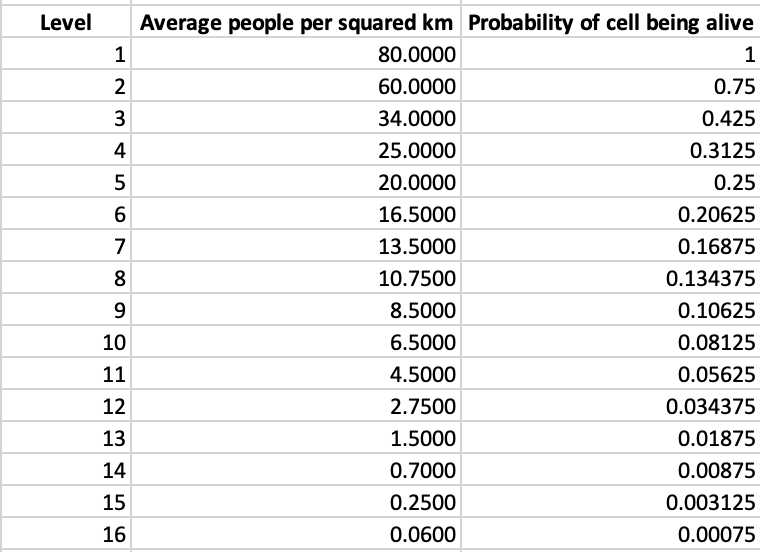

Now, as we have the probability of a cell being alive, we can implement a probabilty for whether or not an alive cell is infected or otherwise. 

To model our fictitious disease, dubbed MatLabitus, we initially wanted 1% of the population to be infected. So, we created a variable for this is probability. 

startingInfectionProbability = 0.1;

We used two random matricies with the same dimensions as the intial image to execute the initial configeration.

State_Probability_Matrix = rand(Rows, Columns);
Infection_Probability_Matrix = rand(Rows, Columns);

The first matrix decided whether or not a cell was alive or unoccupied. For example, if a level 5 cell in the grey-tolerated matrix had a number that was above 0.25 in the State_Probability_Matrix, that cell in the CA matrix would be unoccupied. However, if the number was below 0.25, the cell in the CA matrix would be alive.

The second matrix decided whether or not a cell was infected or healthy. If a cell is condiered to be alive in the CA matrix **AND** that cell in the Infection_Probability_Matrix is less than 0.1, then that cell would be infected. However, if a cell is alive in the CA matrix, but was more that 0.1 in the Infection_Probability_Matrix, then that cell would be considered healthy.

For greater clarity, a diagram below has been inserted to explain the process we used more thoroughly. 

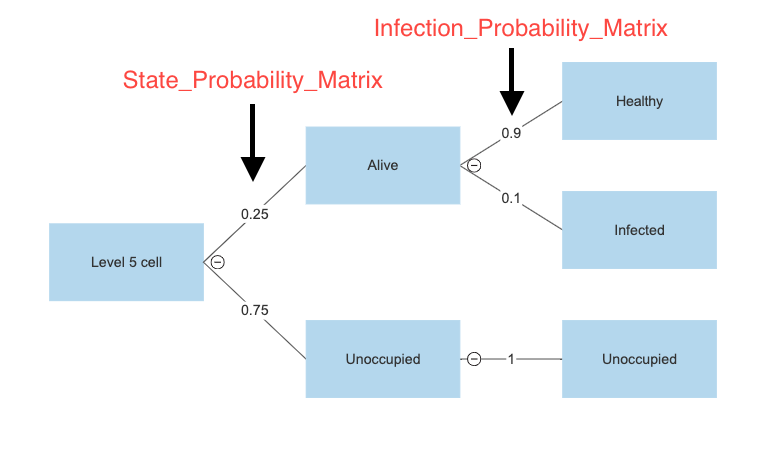

In order to execute this proces through MatLab we created a function. We could not insert this function within the mlx file itself however, so it is in the .m file called **setPopulationDensity.m**.

Below is the code that is contained within in this file;

*function CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, probabilty, index)*

*        z = ones(Rows, Columns);*

*        z(State_Probability_Matrix <= probabilty & Infection_Probability_Matrix >= startingInfectionProbability) = 3;*

*        z(State_Probability_Matrix <= probabilty & Infection_Probability_Matrix < startingInfectionProbability) = 4;*

*    CA(greyimage == index) = z(greyimage == index);*

*end*

The index is the greyscale index for the outlined level.

Three (3) is the number that denotes a healthly cell in the simulator (green).

Four (4) is the number that denotes an infected cell in the simulation (red).

Now, we will call on the function from this mlx file;

% Population Density for L1:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.00075, 240);

% Population Density for L2:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.003125, 225);

% Population Density for L3:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.00875, 210);

% Population Density for L4:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.01875, 195);

% Population Density for L5:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.034375, 180);

% Population Density for L6:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.05625, 165);

% Population Density for L7:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.08125, 150);

% Population Density for L8:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.10625, 135);

% Population Density for L9:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.134375, 120);

% Population Density for L10:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.16875, 105);

% Population Density for L11:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.20625, 90);

% Population Density for L12:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.25, 75);

% Population Density for L13:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.3125, 60);

% Population Density for L14:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.425, 45);

% Population Density for L15:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.75, 30);

% Population Density for L16:
CA = setPopulationDensity(CA, greyimage, startingInfectionProbability, Infection_Probability_Matrix, State_Probability_Matrix, Rows, Columns, 0.99, 15);
 

## Creating the Simulation: Part 2 - Setting Actions

Now that we have the initial configeration sorted, we now need to create a series of actions that would change the state of a cell and the probabilities for those actions to occur. 

We have generated five different actions that could possibly occur in the simulation. Each of these actions are designed make the simulation more realistic. 

- Infection Rate - The probability that a helathy cell will become infected

- Cure Rate - The probability that an infected cell will become healthy

- Death Rate - The probability that an infected cell will die

- Random Death Rate - The probability that a healthy cell will die (this needed to be included in our simulation as it is not realistic for the healthy population to stay alive just if their so happens to not be any infected cells near by; population is not stagnant, people die every day, thus this rule includes needed this factor to makes the simulation more realistic)

- Repopulate Rate - The probability that an unoccupied cell will become alive (again population is not stagnant and is increasing globally)

- Decompose Rate - The rate that a dead cell will become unoccupied (burrying, cremating, etc. dead bodies)

We could of made it that the probability for each of these actions ocurring to be the same for all cells; however, we wanted to extend ourselves and make our cellular automata 'move' differently depended on which part of the masked image the cell was in. This allows that simulation more realistic to the WHO as chance of action occuring in the real world is different depending on geographical location. 

Now, we created a set of probabilities that model the impact the disease 'MatLabitus' has in the real world.

% IFR = Infection Rate
% CR = Cure rate
% DR = Death Rate
% RDR = Random Death Rate
% RR = Repopulate Rate
% BR = Decompose rate
% Matrix example: [IFR CR DR RDR RR BR]

% L1 Probability Matrix
%       IFR     CR     DR    RDR      RR    BR
L1 =  [0.015 0.00002 0.0010 0.00100 0.0005 0.2];
L2 =  [0.015 0.00004 0.0010 0.00090 0.0005 0.2];
L3 =  [0.015 0.00004 0.0010 0.00060 0.0010 0.3];
L4 =  [0.015 0.00006 0.0010 0.00030 0.0010 0.3];
L5 =  [0.015 0.00008 0.0010 0.00010 0.0015 0.3];
L6 =  [0.015 0.00010 0.0010 0.00005 0.0015 0.3];
L7 =  [0.015 0.00012 0.0010 0.00001 0.0020 0.3];
L8 =  [0.015 0.00014 0.0010 0.00002 0.0025 0.4];
L9 =  [0.015 0.00016 0.0010 0.00003 0.0039 0.4];
L10 = [0.015 0.00018 0.0010 0.00004 0.0035 0.4];
L11 = [0.015 0.00020 0.0010 0.00005 0.0040 0.4];
L12 = [0.015 0.00022 0.0009 0.00006 0.0045 0.5];
L13 = [0.015 0.00024 0.0008 0.00007 0.0050 0.5];
L14 = [0.015 0.00026 0.0007 0.00008 0.0055 0.5];
L15 = [0.015 0.00028 0.0006 0.00009 0.0060 0.5];
L16 = [0.015 0.00030 0.0005 0.00010 0.0065 0.5];

% Infection Rate stays the same

% Cure rate increases in more populated areas as generally more populated
% areas have more acess to medical supplies.

% Likewise, Death Rate descreases as level increases.

% Random Death Rate is higher in more isolated areas so that sections that
% just so happen to not have any infected people do not remain stagnant.

% Repopulation rate increases in the more populated areas a there are more
% people.

% Decompose rate increases in more population areas as there are more people
% to bury other people.

Action_Matrix = [L1; L2; L3; L4; L5; L6; L7; L8; L9; L10; L11; L12; L13; L14; L15; L16];


With these probabilities for actions to occur at different levels, we needed to ensure that if cell is a particular level, it will follow its specific level's action probabilities to carry out events.

We can do this by creating a function again. The .m file is called **createRate.m**.

Code below;

*function M = createRate(Rows, Columns, L, greyimage, index)*

*    N = zeros(Rows, Columns);*

*    N(greyimage == 240) = Action_Matrix(1, index);*

*    N(greyimage == 225) = Action_Matrix(2, index);*

*    N(greyimage == 210) = Action_Matrix(3, index);*

*    N(greyimage == 195) = Action_Matrix(4, index);*

*    N(greyimage == 180) = Action_Matrix(5, index);*

*    N(greyimage == 165) = Action_Matrix(6, index);*

*    N(greyimage == 150) = Action_Matrix(7, index);*

*    N(greyimage == 135) = Action_Matrix(8, index);*

*    N(greyimage == 120) = Action_Matrix(9, index);*

*    N(greyimage == 105) = Action_Matrix(10, index);*

*    N(greyimage == 90) = Action_Matrix(11, index);*

*    N(greyimage == 75) = Action_Matrix(12, index);*

*    N(greyimage == 60) = Action_Matrix(13, index);*

*    N(greyimage == 45) = Action_Matrix(14, index);*

*    N(greyimage == 30) = Action_Matrix(15, index);*

*    N(greyimage == 15) = Action_Matrix(16, index);*

*    M = N;*

*end*

Index refers to the column of L and thus what action we are specifying.

The role of this function is to find any cells that are a specific level in the grey image and associates those cells with the probabilities of the actions that are located in another matrix M. This then will cause the simulation to 'move' or carry out our events based on the probabilites of the level.

InfectionRate = createRate(Rows, Columns, Action_Matrix, greyimage, 1);

CureRate = createRate(Rows, Columns, Action_Matrix, greyimage, 2);

DeathRate = createRate(Rows, Columns, Action_Matrix, greyimage, 3);

RandomDeathRate = createRate(Rows, Columns, Action_Matrix, greyimage, 4);

RepopulateRate = createRate(Rows, Columns, Action_Matrix, greyimage, 5);

DecomposeRate = createRate(Rows, Columns, Action_Matrix, greyimage, 6);

## Creating the Simulation: Part 3 - Drawing the Simulation, and Data Collection

Now, with our initial configuration of the probability of actions occuring, we started thinking about how this simulation will look.

For the cellular automata simulation we wanted a figure to appear with the same number of cells as pixels in the image we are simulating, and we want it to update every time an event is carried out. For this simulation, we set the time taken for an event to occur as one day. 

In order for the figure to be visible, we implemented the following code;

ax = figure;
set(ax, 'Visible', 'on')

Now, we wanted to possess the ability to stop the simulation at any point we choose. In order to do this we created a function that allows the user to press any button on their keyboard to end the simulation. The file for this function is **KeyPressed.m**.

Code included below;

*function KeyPressed(~, ~)*

*    evalin('base', 'done = true;')*

*end*

% Naming the function 'KeyPressed'
set(gcf, 'KeyPressFcn', @KeyPressed)
handle = imagesc(CA);
title('MatLabitus Disease Spread - Press any key to finish');


Clearly, we needed to ensure the figure was updated at every event and that the colours are the same after every event. To do this we created another function that refreshes data after every event, and then resets that colour map. This file name for this function is **draw.m**.

Code inclueded below;

*function draw(CA, handle, mymap, ax)*

*    handle.CData = CA;*

*    %set(handle, 'cdata', A, mymap);*

*    drawnow*

*    colormap(ax, mymap)*

*end*

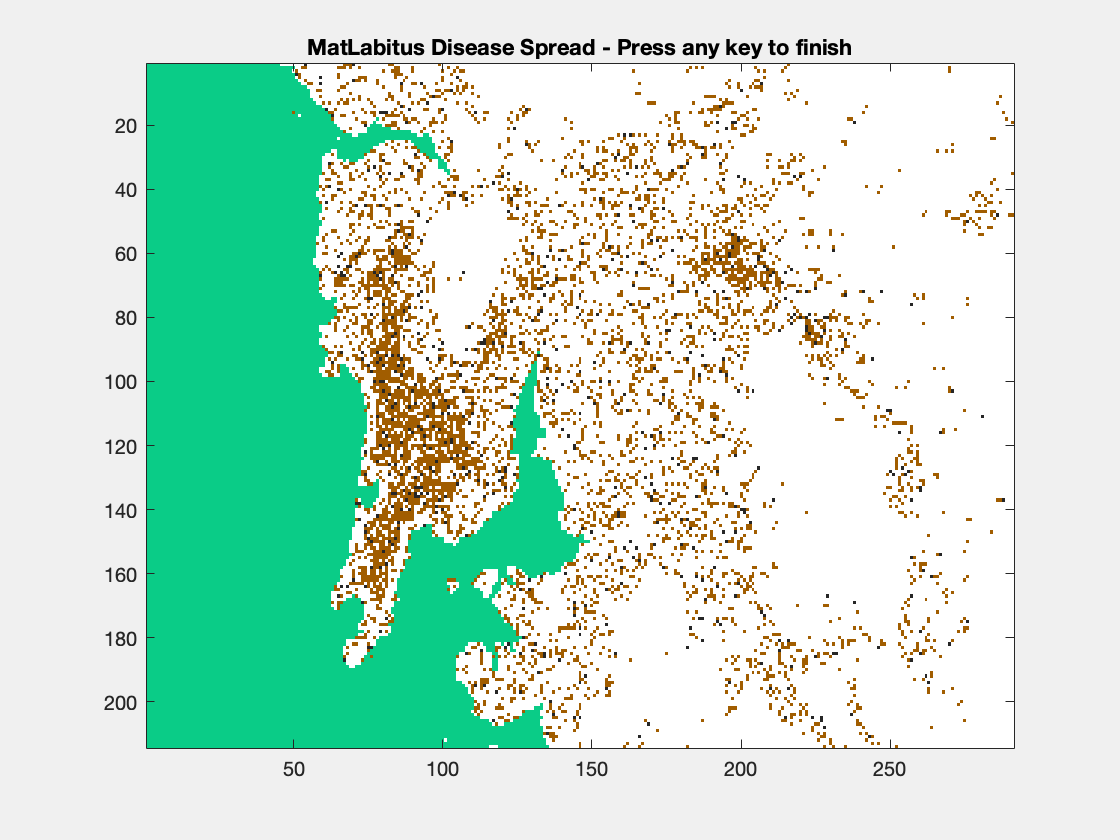

% Calling the function Draw
draw(CA, handle, mymap, ax);

As our we have our simulation running, we want to extrapolate data from it for the WHO to actually use. We needed to be able to clearly see the trends of how many people are healthy, infected, or dying, and at what rate these numbers increase or decrease. 

To do this, we programmed a graph to run alongside the cellular automata simulation of the disease, constantly updating the data values. 

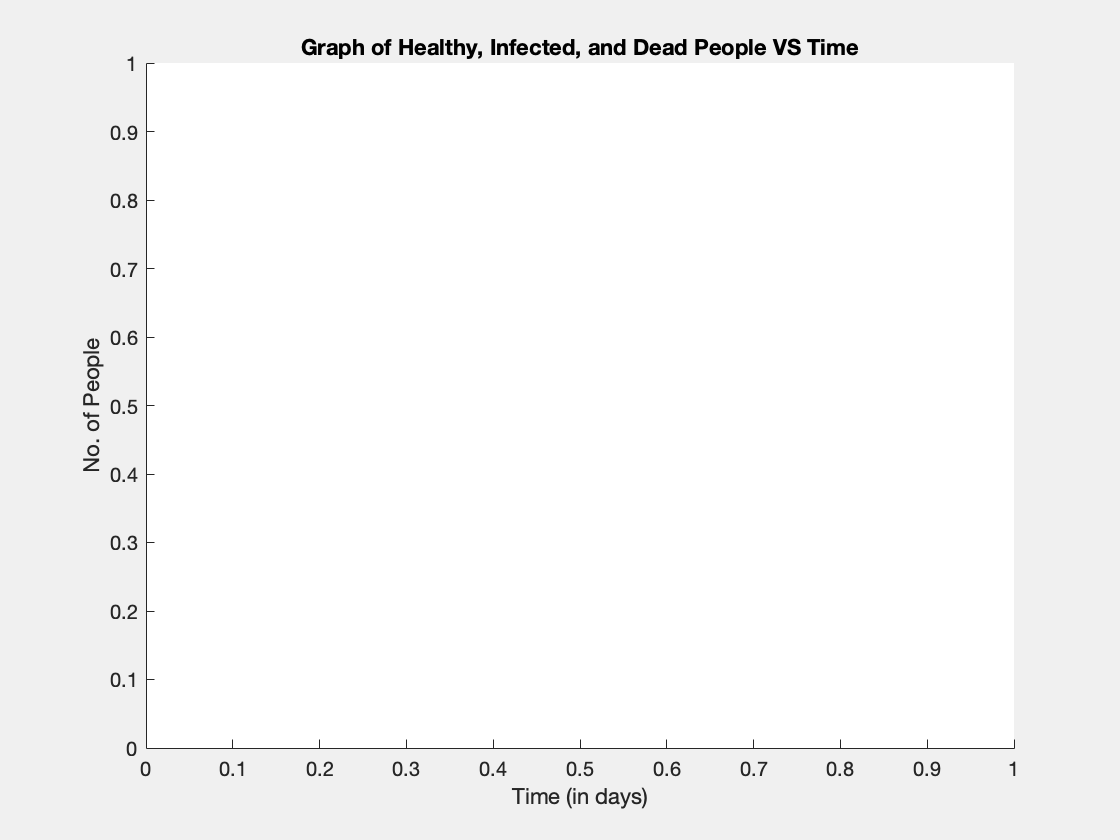

figure;
ax2 = gca;
x_step = 0;
h1 = animatedline(ax2, 'Color','g'); % Healthy/Green
h2 = animatedline(ax2, 'Color', 'r'); % Infected/Red
h3 = animatedline (ax2, 'Color', 'k'); % Dead/Grey
set(gcf, 'Visible', 'on')
title('Graph of Healthy, Infected, and Dead People VS Time')
xlabel('Time (in days)')
ylabel('No. of People')

The three lines generated in this graph are to show the total number of cells that are healthy, infected, or dead that are presented in the simulation as time goes on.

To do this, a new figure was opened for the graph itself, as to not overwrite our simulation. Then three animated lines where implemented into the graph using the ‘animatedline’ command and the ‘addpoints’ command so that the lines could update with the new data values shown alongside our simulation. The data itself that the graph displayed was obtained by summing up the amount of threes (healthy), fours (infected), and fives (dead) in our final matrix ‘CA’, that constructs the simulation, to gather all the data for the displayed states together. 

The overall number of cells that were in each state in the simulation were displayed more clearly by creating strings of these values, using the ‘num2str’, command and then implementing that code into our legend.* 

**This bit of the code is implemented in the next section as it required to be in the while loop. However, for clarity of the report it will be explained below;*

*    % Number of 3's in matrix A (3 = Green/Healthy)*

*    sum_3s = sum(A(:) == 3);*

*    % Number of 4's in matrix A (4 = Red/Infected)*

*    sum_4s = sum(A(:) == 4);*

*    % Number of 5's in matrix A (5 = Grey/Dead)*

*    sum_5s = sum(A(:) == 5);*

*    x_step = x_step + 1;*

*    addpoints(h1, x_step, sum_3s); % Healthy*

*    addpoints(h2, x_step, sum_4s); % Infected*

*    addpoints(h3, x_step, sum_5s); % Dead*

*    Str3 = num2str(sum_3s);*

*    Str4 = num2str(sum_4s);*

*    Str5 = num2str(sum_5s);*

*    legend(ax2, {['Healthy: ' Str3], ['Infected: ' Str4], ['Deceased: ' Str5]})*

From this, the data that our disease simulation displayed could be interpreted with greater ease as the graph processed the data to a simpler format for viewing.

## Creating the Simulation: Part 4 - The Actual Simulation

Now that we have the starting configuration, the probability of actions occuring for each different section, and the graphs, ready for analysis, it was time to actaully write the rules that govern wether an action will occur or not. 

In order to do that we needed to define what is considered a north, south, east, or west neighbour. This is important as the simulations next move is based off of "who" is around a cell.

north = [Rows 1:Rows-1];         % indices of north neighbour
east  = [2:Columns 1];           % indices of east neighbour
south = [2:Rows 1];              % indices of south neighbour
west  = [Columns 1:Columns-1];   % indices of west neighbour


With the neighbours defined, we could then define the rules that carry out the actions. 

done = false;
while ~done
    % Random Seed
    RS = rand(Rows, Columns);
    

The Random Seed gives a decimal number between 0 and 1 to all the cells in CA. These numbers will be later used to determine whether or not an action occurs based on the Action_Matrix we constructed earlier.

Though, in order to do this, we first needed to find out how many neighbouring cells around a particular cell are unoccupied (1), walls (2), healthy (3), infected (4), or dead(5). We did this through another function called **getNeighbours.m**.

    % Amount of certain type of neighbours
    unnocupied_neighbours = getNeighbours(CA, 1, north, south, east, west);
    wall_neighbours = getNeighbours(CA, 2, north, south, east, west);
    healthy_neighbours = getNeighbours(CA, 3, north, south, east, west);
    infected_neighbours = getNeighbours(CA, 4, north, south, east, west);
    dead_neighbours = getNeighbours(CA, 5, north, south, east, west);

As the number of neighbours are defined, the condtions can now be set.

We will go through all the conditions that will cause a cell to become unoccupied:

The first condition occurs if there is a cell that is dead and there is at least a single healthy neighbour present and the Random Seed value of that cell is less than 0.4.

    % ## Unnocupied actions 1
    unnocupied_rule_1 = (CA(:, :)==5) & (healthy_neighbours >= 1) & (RS(:, :) < 0.4);
 

The second condition occurs if there is a cell that is dead and the random seed values is less than the decomposed rate for that cell's level (previously defined in Action_Matrix).

    % Chance to decompose
    unnocupied_rule_2 = (CA(:, :)==5) & (RS(:, :) < DecomposeRate);

These two actions are an or gate, meaning that if either of them are true, then the cell becomes unoccupied. Likewise, if both of them are true then the cell will become unoccupied as well. 

    % Apply Actions  
    CA(unnocupied_rule_1 | unnocupied_rule_2) = 1; 
 

These next conditions determine if a cell will become, and remain, healthy; 

- Repopulating if there are 2 or more living neighbours.

    healthy_rule_1 = (CA(:, :)==1) & ((healthy_neighbours + infected_neighbours) >= 2) & (RS(:, :) < RepopulateRate);

        2.  Curing if there are more than 2 healthy neighbours.

    healthy_rule_2 = (CA(:, :)==4) & (healthy_neighbours > 2) & (RS(:, :) < CureRate);
    %Apply Actions  
    CA(healthy_rule_1 | healthy_rule_2) = 3;   
    

The next condition determines if a cell becomes infected;

- There are 2 or more infected neighbours.

    infected_rule_1 = (CA(:, :)==3) & (infected_neighbours >= 2) & (RS(:, :) < InfectionRate);
     %Apply Actions   
    CA(infected_rule_1) = 4;
     

These next conditions determine if a cell becomes dead;

- Cell dies from infection.

    dead_rule_1 = (CA(:, :)==4) & (RS(:, :) < DeathRate);

        2.  Cells dies a random death.

    dead_rule_2 = (CA(:, :)==4 | CA(:,:)==3) & (RS(:, :) < RandomDeathRate);
 %Apply Actions       
    CA(dead_rule_1 | dead_rule_2) = 5;
 

This code here ensures the celluar automata is updated after every action;

    % Update the state
    draw(CA, handle, mymap, ax);

Here is the data analysis code for that graph that was explained earlier;

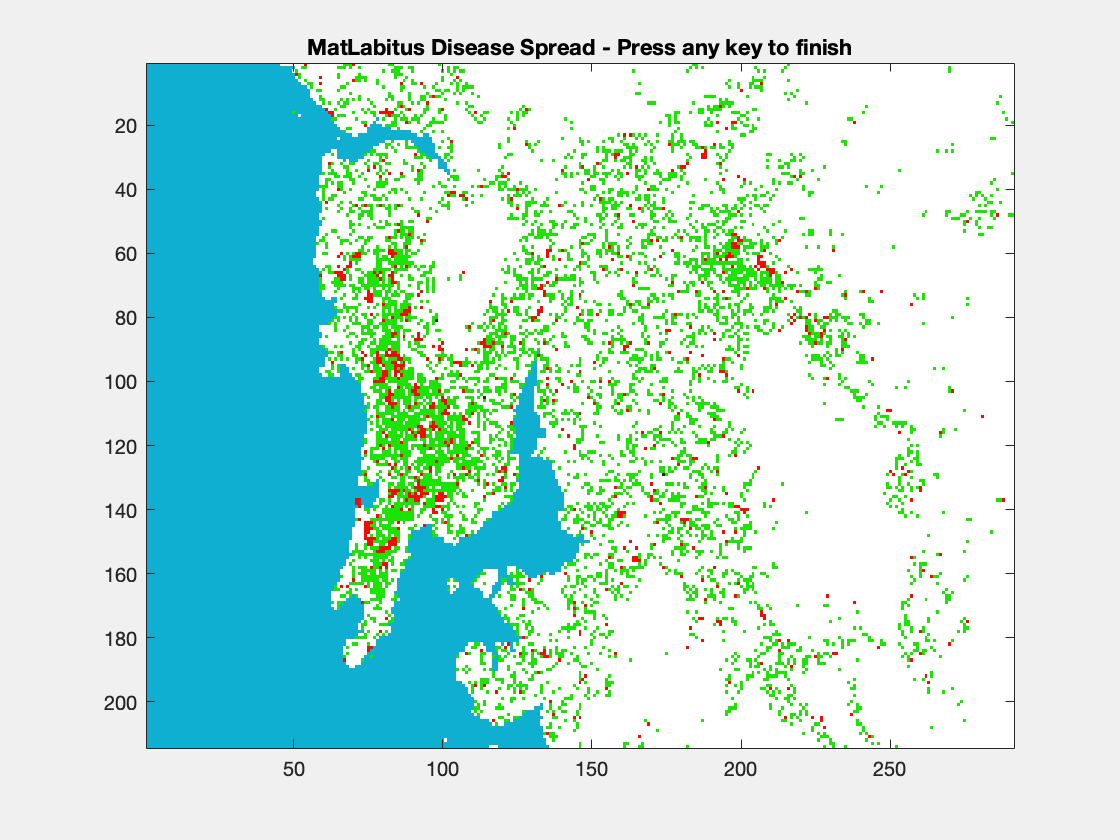

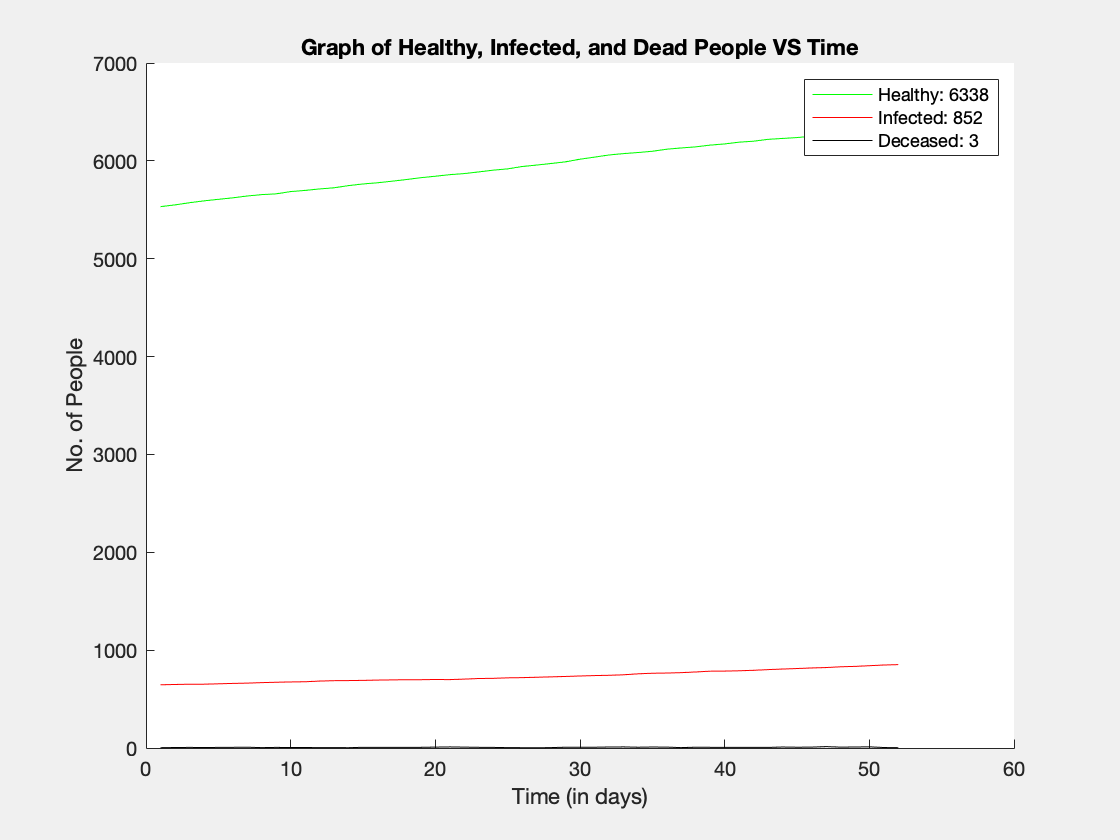

    % Number of 3's in matrix A (3 = Green/Healthy)
    sum_3s = sum(CA(:) == 3);
    % Number of 4's in matrix A (4 = Red/Infected)
    sum_4s = sum(CA(:) == 4);
    % Number of 5's in matrix A (5 = Grey/Dead)
    sum_5s = sum(CA(:) == 5);
    
    x_step = x_step + 1;
    addpoints(h1, x_step, sum_3s); % Healthy
    addpoints(h2, x_step, sum_4s); % Infected
    addpoints(h3, x_step, sum_5s); % Dead
    Str3 = num2str(sum_3s);
    Str4 = num2str(sum_4s);
    Str5 = num2str(sum_5s);
    
    legend(ax2, {['Healthy: ' Str3], ['Infected: ' Str4], ['Deceased: ' Str5]})
    % shows what the lines mean and also shows the total no. of people who
    % are healthy, infected, or dead at that specific time in the
    % simulation.
end

## Conclusion:

With this simulation one can find analyse the number of healthy cells, infected cell and dead cell after a given time period. The simulation will not specifically tell you how many people are dead; in order to that we would need to work out how many square km each pixel is worth but that would be different for evey picture. Not to mention that the website where we aquired the heat maps did not have a scale bar on their map. If this report was to be extended this would be area where more research could be done to get exact numbers of people who are dead, alive and infected.

We hope the WHO finds our work valuable and seeks to work with our simulation to help prevent future virus/disease/infectious outbreaks and save countless lives. 